**Beyza Ipekci**

**Johnathan Avila**

**Thermo HW 4**

**02/21/19**

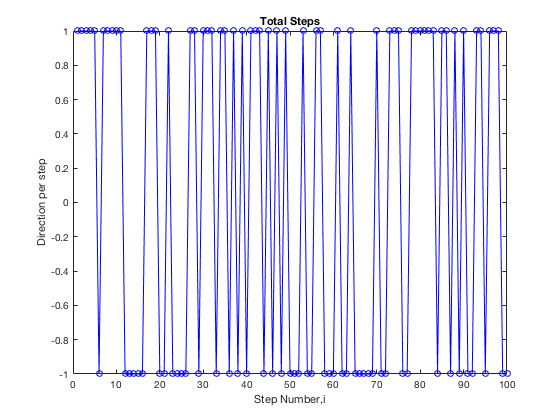

clear all;
close all;

deltax = (rand(1,100) < 0.5)*2-1; %generate randomized number of either -1 and +1
i = 1:100; %step number 

figure (1)

plot(i,deltax,'-ob'); %plot step number vs distance per step

xlabel('Step Number,i')
ylabel('Direction per step')
title('Total Steps');

xlim([0 100])
ylim([-1 1])

## **Cumulative Distance**

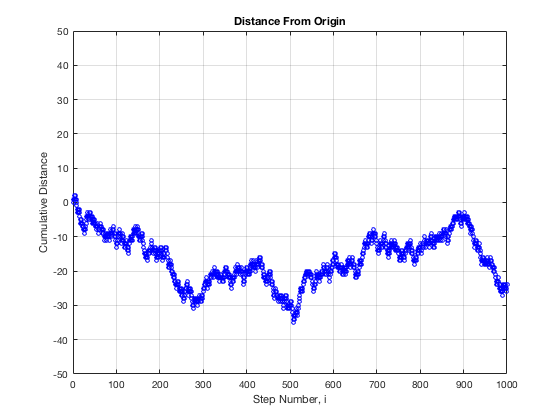


N = 1000; 
i = 0;
sumdeltaX = 0;

for n = 1:N %for loop with N number of iterations
   
    deltax = (rand(1) < 0.5)*2-1; %generates randomized number of either -1 and +1
    sumdeltaX = deltax + sumdeltaX; %cumulative distance
    i = i + 1; %number of steps
   
    figure (2)
    
    plot(i,sumdeltaX,'ob','MarkerSize',4); %plot cumulative distance vs step number 
    hold on;
    grid on;
    
end 

xlabel('Step Number, i')
ylabel('Cumulative Distance')
title('Distance From Origin');

xlim([0 1000])
ylim([-50 50])

## **Mean-Squared Displacement**

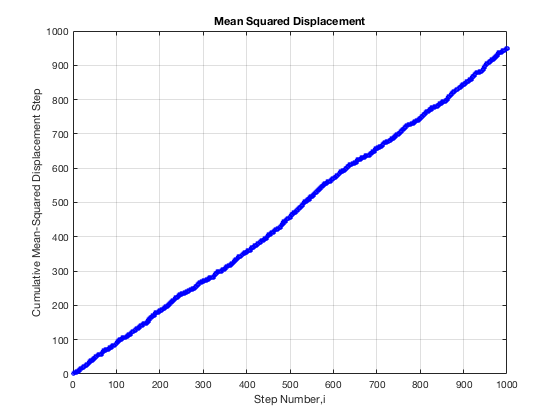

N = 1000; % number of iterations
i = 0;
sumdeltaX = 0;

for n = 1:N %for loop with N number of iterations
   
    deltax = (rand(1) < 0.5)*2-1; %generate randomized number of -1 and +1
    sumdeltaX = ((deltax^2) + sumdeltaX)- deltax; %cumulative mean-squared distance 
    i = i + 1; %total steps
   
    figure (3)
    
    plot(i,sumdeltaX,'ob','MarkerSize',4);
    hold on;
    grid on;
    
end

xlabel('Step Number,i')
ylabel('Cumulative Mean-Squared Displacement Distance')
title('Mean Squared Displacement');

xlim([0 1000])
ylim([0 1000])

## **Gaussian Histogram**

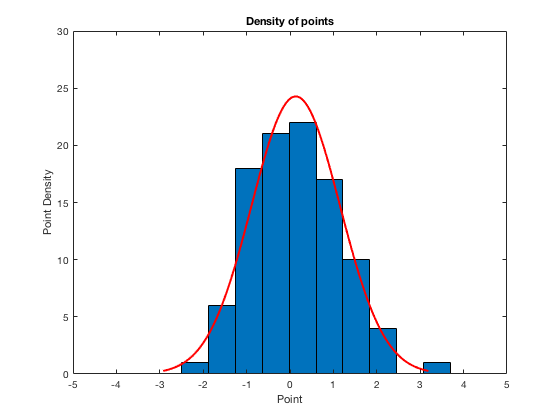


gauss = normrnd(0,1,100,1); %Generates a size of 100 with mean 10 and var 1 (1D)

figure (4)

histfit(gauss); % plots histogram w/ gaussian best fit 

xlabel('Point')
ylabel('Point Density')
title('Density of points');

xlim([-5 5])
ylim([0 30])

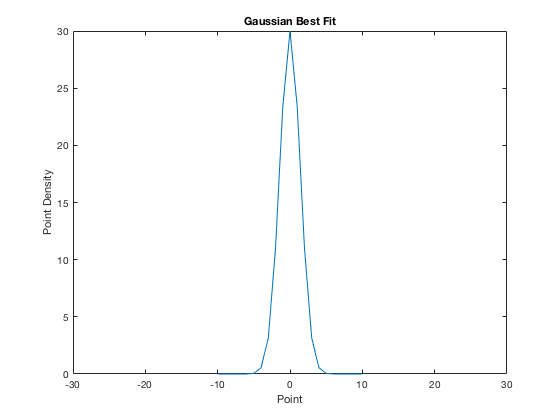

 
 
N=30; %N_o
sigma=2; %Sigma
x=-10:10; %x variable
Numpts = N*exp(-x.^2/sigma.^2); %gaussian equation

figure (5)

plot(x,Numpts); %shows that 1d random walk point density histogram plot approcahes gaussian curve plot 

xlabel('Points')
ylabel('Point Density')
title('Gaussian Best Fit');

xlim([-30 30])
ylim([0 30])

## **Entropy **

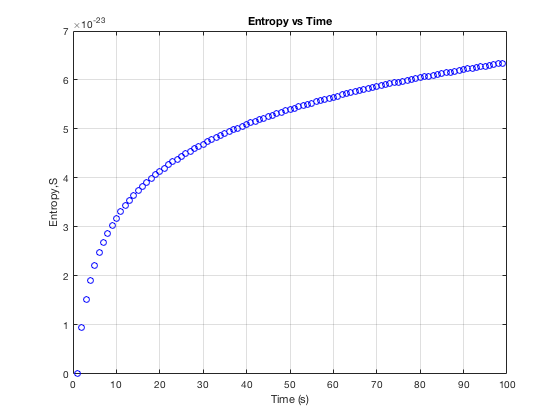


k=1.38*10.^-23; %boltzmann's constant  
N=100; %number of locations 
j=1;
t = 1:N-1; %time vector

for x=1:N-1 %posibble locations 
    S=k*log(x); %calculate entropy for locations occupied
    Snew=S; %replace old S value with new S value
    s(j)=Snew; %store entropy values
    j=j+1; 
end

figure (6)

plot(t,s, 'ob') %plot entropy vs time
hold on;
grid on;

xlabel('Time (s)')
ylabel('Entropy,S')
title('Entropy vs Time')